# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
%Deci.Folder.Raw         = ['/Users/RobReinhart/Documents/Data/Behavioral'];              % Raw Data Folder Directory
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\AB2\Behav'];
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.PCom               = false;  
%Deci.Folder.Version     = ['/Users/RobReinhart/Documents/Data/Processed_displace'];        % Output Folder Directory
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\AB2\ProcessedData'];

## 1. Trial Definitions

% Trial definition infomaton
Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = 1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];      

## 5. Plotting

CollapseBlocks = true;

Plot_doublet;

Deci.Run.Behavior = true;
Deci.Run.Extra = false;

## ** 6. Run**

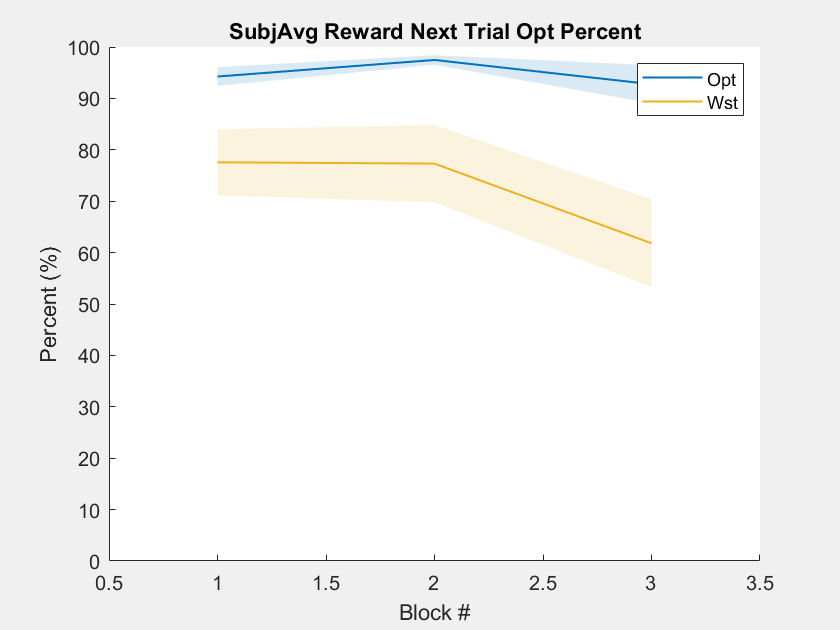

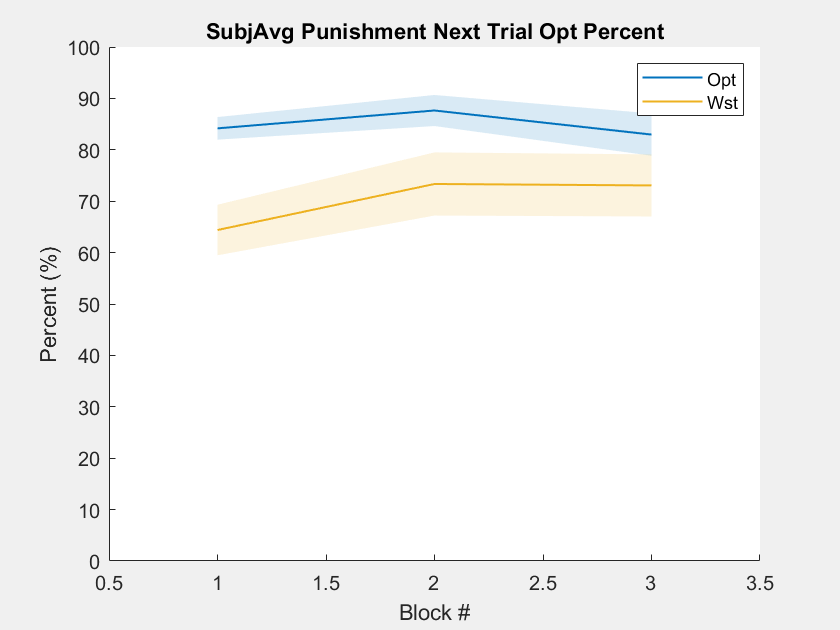

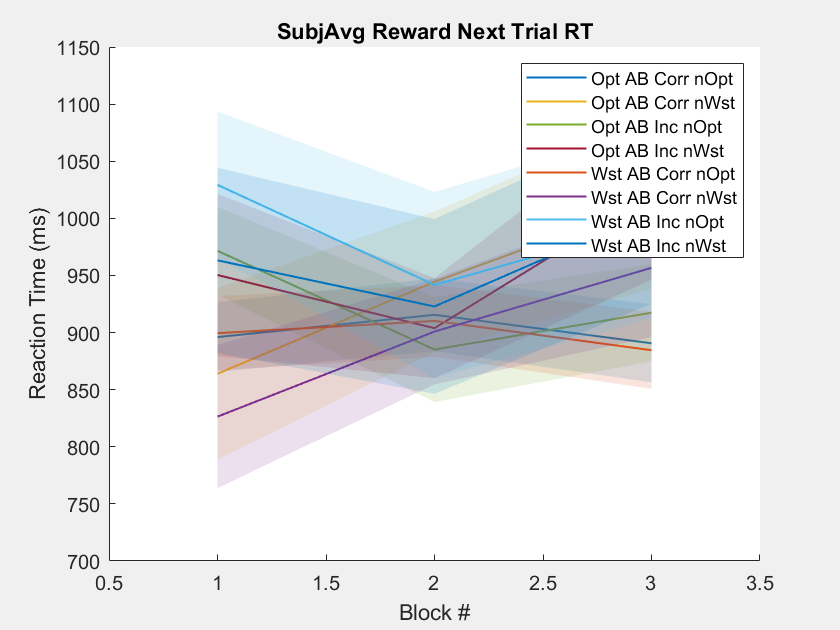

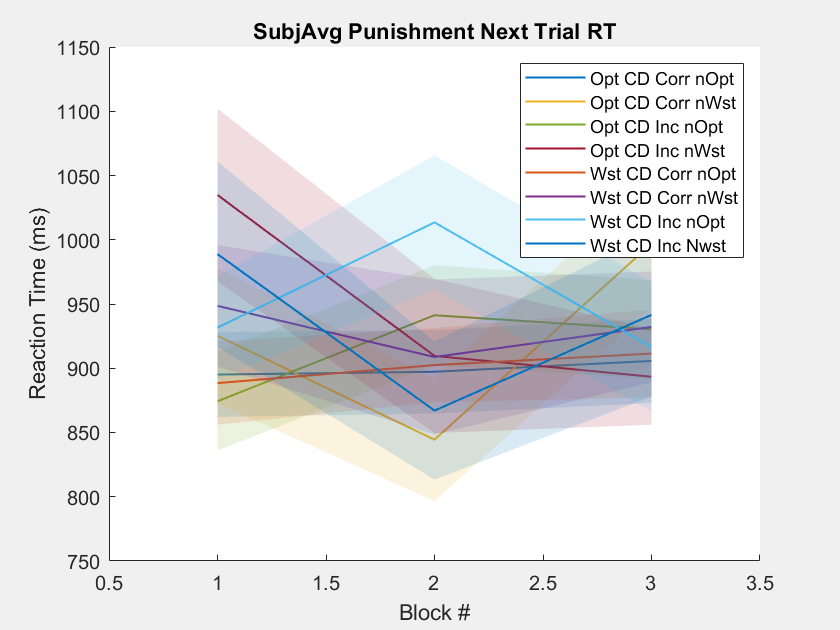

Deci_Backend(Deci);